# Computation and analysis of microbe-microbe metabolic interactions

## Author: Almut Heinken, Molecular Systems Physiology Group, National University of Ireland Galway.

This tutorial demonstrates how to join a given list of microbial COBRA models in all possible combinations and compute the metabolic

interactions between the microbes depending on the implemented diet. Moreover, the tradeoff between the growth of different joined microbes is computed. The tutorial can be adapted to any number of AGORA models and dietary conditions analyzed.

## Requirements

This tutorial requires the Parallel Computing Toolbox, Bioinformatics Toolbox, and Statistics and Machine Learning Toolbox add-ons in MATLAB.

## Initialize the COBRA Toolbox

%initCobraToolbox

## Prepare input data and models

We will use the AGORA resource (Magnusdottir et al., Nat Biotechnol. 2017 Jan;35(1):81-89) in this tutorial. AGORA version 1.03 is available at https://github.com/VirtualMetabolicHuman/AGORA. Download AGORA and place the models into a folder.

modPath= 'C:\Users\u0128864\Documents\MATLAB\AGORA\human2'
%change ligne 34 and medium
%modPath='C:\Users\u0128864\Documents\MATLAB\AGORA\ref_mixed\plus1\'
%modPath='C:\Users\u0128864\Documents\MATLAB\AGORA\refined\models\'

Import a file with information on the AGORA organisms including reconstruction names and taxonomy.

files = dir(modPath)

modPath = 'C:\Users\u0128864\Documents\MATLAB\AGORA\human2'

modelList={}

files = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


for j=3:length(files)
    modelList{j-2,1}=files(j).name;


modelList =

  0×0 empty cell array



    modelList{j-2,1}=modelList{j-2,1}(1:end-4);
end

modelList

Note: if you get a 'file not found' error for AGORA_infoFile.xlsx, please run initCobraToolbox and ensure that the cobratoolbox/papers folder is in the MATLAB path.

## Creation of pairwise models

For the sake of this tutorial, we will use ten random AGORA reconstructions from the info file.

Uncomment the following line to join all AGORA reconstructions in all combinations. NOTE: this is very time-consuming due to the large number of model combinations analyzed.

modelList=infoFile(2:end,1);

You may also enter a custom selection of AGORA reconstructions as a cell array named modelList.

Let us define some parameters for joining the models. Set the coupling factor c, which defined how the flux through all reactions in a model is coupled to the flux through its biomass reaction. Allowed flux span through each reaction= -(c * flux(biomass)) to +(c * flux(biomass)).

c = 400;

modelList = 2×1 cell array
    {'Bacteroides_caccae_ATCC_43185' }
    {'Bifidobacterium_longum_NCC2705'}


Set the threshold u, which defines the flux through each reaction that is allowed if flux through the biomass reaction is zero.

u = 0;

Define whether or not genes from the models are merged and kept in the joined models. If set to true the joining is more time-consuming.

mergeGenes = false;

Define the number workers for parallel pool to allow parallel computing.Recommended if a large number of microbe models is computed. Set to zero if parallel computing is not available.

numWorkers = 6;

path where to save results

mkdir('C:\Users\u0128864\Documents\MMT\AGORA');
resPath = 'C:\Users\u0128864\Documents\MMT\AGORA\'

Join the models in all possible combinations.

dir(modPath)

modelList

resPath = 'C:\Users\u0128864\Documents\MMT\AGORA\'

resPath

%modelList=modelList(3:end-3)
%for j=1:length(modelList)

.                                   
..                                  
Bacteroides_caccae_ATCC_43185.xml   
Bifidobacterium_longum_NCC2705.xml  




%    n=modelList{j}

modelList = 2×1 cell array
    {'Bacteroides_caccae_ATCC_43185' }
    {'Bifidobacterium_longum_NCC2705'}


%    modename = strcat(modPath,n,'.xml')

resPath = 'C:\Users\u0128864\Documents\MMT\AGORA\'

%    model=readCbModel(modename)
%end


%modelList={'Bacteroides_thetaiotaomicron_VPI_5482','Faecalibacterium_prausnitzii_A2_165.mat','Roseburia_intestinalis_L1_82.mat'}
joinModelsPairwiseFromList(modelList,modPath,'pairwiseModelFolder', resPath,'c',c,'u',u,'mergeGenesFlag',mergeGenes,'numWorkers',numWorkers);

The following fields are missing in several models, they will not be merged:
25%     [..........         100%    [........................................]



## Computation of pairwise interactions

The interactions between all microbes joined in the first step will be simulated on given dietary conditions. Here, we will use four dietary conditions used in Magnusdottir et al., Nat Biotechnol. 2017.: Western Diet without oxygen, Western Diet with oxygen, High fiber diet without oxygen, and High fiber diet with oxygen. Let us define the input parameters for the simulation of pairwise interactions.

Name the four dietary conditions that will be simulated.

conditions={'DC1','DC3','YCAG'}%,'YCAG','YCGMS','YCFA','mMCB','YCGD'}

conditions = 1×3 cell array
    {'DC1'}    {'DC3'}    {'YCAG'}


Define the corresponding constraints to implement for each diet. The input file needs to be a string array.

%DCS1
dietConstraints{1}={'EX_fru[u]','-0.14899','1000';'EX_glc_D[u]','-0.14899','1000';'EX_gal[u]','-0.14899','1000';'EX_man[u]','-0.14899','1000';'EX_mnl[u]','-0.14899','1000';'EX_fuc_L[u]','-0.14899','1000';'EX_glcn[u]','-0.14899','1000';'EX_rmn[u]','-0.14899','1000';'EX_arab_L[u]','-0.17878','1000';'EX_drib[u]','-0.17878','1000';'EX_rib_D[u]','-0.17878','1000';'EX_xyl_D[u]','-0.17878','1000';'EX_oxa[u]','-0.44696','1000';'EX_lcts[u]','-0.074493','1000';'EX_malt[u]','-0.074493','1000';'EX_sucr[u]','-0.074493','1000';'EX_melib[u]','-0.074493','1000';'EX_cellb[u]','-0.074493','1000';'EX_tre[u]','-0.074493','1000';'EX_strch1[u]','-0.25734','1000';'EX_amylopect900[u]','-1.5673e-05','1000';'EX_amylose300[u]','-4.7019e-05','1000';'EX_arabinan101[u]','-0.00016628','1000';'EX_arabinogal[u]','-2.1915e-05','1000';'EX_arabinoxyl[u]','-0.00030665','1000';'EX_bglc[u]','-7.05e-08','1000';'EX_cellul[u]','-2.8212e-05','1000';'EX_dextran40[u]','-0.00017632','1000';'EX_galmannan[u]','-1.4106e-05','1000';'EX_glcmannan[u]','-3.2881e-05','1000';'EX_homogal[u]','-0.00012823','1000';'EX_inulin[u]','-0.00047019','1000';'EX_kestopt[u]','-0.0028212','1000';'EX_levan1000[u]','-1.4106e-05','1000';'EX_lmn30[u]','-0.00047019','1000';'EX_lichn[u]','-8.2976e-05','1000';'EX_pect[u]','-3.3387e-05','1000';'EX_pullulan1200[u]','-1.1755e-05','1000';'EX_raffin[u]','-0.0047019','1000';'EX_rhamnogalurI[u]','-1.4492e-05','1000';'EX_rhamnogalurII[u]','-0.00026699','1000';'EX_starch1200[u]','-1.1755e-05','1000';'EX_xylan[u]','-3.2059e-05','1000';'EX_xyluglc[u]','-1.3146e-05','1000';'EX_arachd[u]','-0.003328','1000';'EX_chsterol[u]','-0.004958','1000';'EX_glyc[u]','-1.7997','1000';'EX_hdca[u]','-0.39637','1000';'EX_hdcea[u]','-0.036517','1000';'EX_lnlc[u]','-0.35911','1000';'EX_lnlnca[u]','-0.017565','1000';'EX_lnlncg[u]','-0.017565','1000';'EX_ocdca[u]','-0.16928','1000';'EX_ocdcea[u]','-0.68144','1000';'EX_octa[u]','-0.012943','1000';'EX_ttdca[u]','-0.068676','1000';'EX_ala_L[u]','-1','1000';'EX_cys_L[u]','-1','1000';'EX_ser_L[u]','-1','1000';'EX_arg_L[u]','-0.15','1000';'EX_his_L[u]','-0.15','1000';'EX_ile_L[u]','-0.15','1000';'EX_leu_L[u]','-0.15','1000';'EX_lys_L[u]','-0.15','1000';'EX_asn_L[u]','-0.225','1000';'EX_asp_L[u]','-0.225','1000';'EX_thr_L[u]','-0.225','1000';'EX_glu_L[u]','-0.18','1000';'EX_met_L[u]','-0.18','1000';'EX_gln_L[u]','-0.18','1000';'EX_pro_L[u]','-0.18','1000';'EX_val_L[u]','-0.18','1000';'EX_phe_L[u]','-1','1000';'EX_tyr_L[u]','-1','1000';'EX_gly[u]','-0.45','1000';'EX_trp_L[u]','-0.08182','1000';'EX_12dgr180[u]','-1','1000';'EX_26dap_M[u]','-1','1000';'EX_2dmmq8[u]','-1','1000';'EX_2obut[u]','-1','1000';'EX_3mop[u]','-1','1000';'EX_4abz[u]','-1','1000';'EX_4hbz[u]','-1','1000';'EX_5aop[u]','-1','1000';'EX_ac[u]','-1','1000';'EX_acald[u]','-1','1000';'EX_acgam[u]','-1','1000';'EX_acmana[u]','-1','1000';'EX_acnam[u]','-1','1000';'EX_ade[u]','-1','1000';'EX_adn[u]','-1','1000';'EX_adocbl[u]','-1','1000';'EX_akg[u]','-1','1000';'EX_ala_D[u]','-1','1000';'EX_amet[u]','-1','1000';'EX_amp[u]','-1','1000';'EX_anth[u]','-1','1000';'EX_arab_D[u]','-1','1000';'EX_avite1[u]','-1','1000';'EX_btn[u]','-1','1000';'EX_ca2[u]','-1','1000';'EX_cbl1[u]','-1','1000';'EX_cgly[u]','-1','1000';'EX_chol[u]','-1','1000';'EX_chor[u]','-1','1000';'EX_cit[u]','-1','1000';'EX_cl[u]','-1','1000';'EX_cobalt2[u]','-1','1000';'EX_csn[u]','-1','1000';'EX_cu2[u]','-1','1000';'EX_cytd[u]','-1','1000';'EX_dad_2[u]','-1','1000';'EX_dcyt[u]','-1','1000';'EX_ddca[u]','-1','1000';'EX_dgsn[u]','-1','1000';'EX_etoh[u]','-1','1000';'EX_fald[u]','-1','1000';'EX_fe2[u]','-1','1000';'EX_fe3[u]','-1','1000';'EX_fe3dcit[u]','-1','1000';'EX_fol[u]','-1','1000';'EX_for[u]','-1','1000';'EX_fum[u]','-1','1000';'EX_gam[u]','-1','1000';'EX_glu_D[u]','-1','1000';'EX_glyc3p[u]','-1','1000';'EX_gsn[u]','-1','1000';'EX_gthox[u]','-1','1000';'EX_gthrd[u]','-1','1000';'EX_gua[u]','-1','1000';'EX_h[u]','-1','1000';'EX_h2[u]','-1','1000';'EX_h2s[u]','-1','1000';'EX_hom_L[u]','-1','1000';'EX_hxan[u]','-1','1000';'EX_indole[u]','-1','1000';'EX_ins[u]','-1','1000';'EX_k[u]','-1','1000';'EX_lac_L[u]','-1','1000';'EX_lanost[u]','-1','1000';'EX_mal_L[u]','-1','1000';'EX_metsox_S_L[u]','-1','1000';'EX_mg2[u]','-1','1000';'EX_mn2[u]','-1','1000';'EX_mobd[u]','-1','1000';'EX_mqn7[u]','-1','1000';'EX_mqn8[u]','-1','1000';'EX_na1[u]','-1','1000';'EX_nac[u]','-1','1000';'EX_ncam[u]','-1','1000';'EX_nmn[u]','-1','1000';'EX_no2[u]','-1','1000';'EX_no3[u]','-1','1000';'EX_orn[u]','-1','1000';'EX_pheme[u]','-1','1000';'EX_phyQ[u]','-1','1000';'EX_pi[u]','-1','1000';'EX_pime[u]','-1','1000';'EX_pnto_R[u]','-1','1000';'EX_ptrc[u]','-1','1000';'EX_pydam[u]','-1','1000';'EX_pydx[u]','-1','1000';'EX_pydx5p[u]','-1','1000';'EX_pydxn[u]','-1','1000';'EX_q8[u]','-1','1000';'EX_retinol[u]','-1','1000';'EX_ribflv[u]','-1','1000';'EX_sel[u]','-1','1000';'EX_sheme[u]','-1','1000';'EX_so4[u]','-1','1000';'EX_spmd[u]','-1','1000';'EX_succ[u]','-1','1000';'EX_thf[u]','-1','1000';'EX_thm[u]','-1','1000';'EX_thymd[u]','-1','1000';'EX_ura[u]','-1','1000';'EX_uri[u]','-1','1000';'EX_vitd3[u]','-1','1000';'EX_xan[u]','-1','1000';'EX_zn2[u]','-1','1000';'EX_meoh[u]','-10','1000';'EX_h2o[u]','-10','1000'};

%DCS2
dietConstraints{2}={'EX_fru[u]','-0.03947','1000';'EX_glc_D[u]','-0.03947','1000';'EX_gal[u]','-0.03947','1000';'EX_man[u]','-0.03947','1000';'EX_mnl[u]','-0.03947','1000';'EX_fuc_L[u]','-0.03947','1000';'EX_glcn[u]','-0.03947','1000';'EX_rmn[u]','-0.03947','1000';'EX_arab_L[u]','-0.04737','1000';'EX_drib[u]','-0.04737','1000';'EX_rib_D[u]','-0.04737','1000';'EX_xyl_D[u]','-0.04737','1000';'EX_oxa[u]','-0.11842','1000';'EX_lcts[u]','-0.01974','1000';'EX_malt[u]','-0.01974','1000';'EX_sucr[u]','-0.01974','1000';'EX_melib[u]','-0.01974','1000';'EX_cellb[u]','-0.01974','1000';'EX_tre[u]','-0.01974','1000';'EX_strch1[u]','-0.06818','1000';'EX_amylopect900[u]','-0.00034722','1000';'EX_amylose300[u]','-0.0010417','1000';'EX_arabinan101[u]','-0.0036837','1000';'EX_arabinogal[u]','-0.0004855','1000';'EX_arabinoxyl[u]','-0.0067935','1000';'EX_bglc[u]','-1.5625e-06','1000';'EX_cellul[u]','-0.000625','1000';'EX_dextran40[u]','-0.0039062','1000';'EX_galmannan[u]','-0.0003125','1000';'EX_glcmannan[u]','-0.00072844','1000';'EX_homogal[u]','-0.0028409','1000';'EX_inulin[u]','-0.010417','1000';'EX_kestopt[u]','-0.0625','1000';'EX_levan1000[u]','-0.0003125','1000';'EX_lmn30[u]','-0.010417','1000';'EX_lichn[u]','-0.0018382','1000';'EX_pect[u]','-0.00073965','1000';'EX_pullulan1200[u]','-0.00026042','1000';'EX_raffin[u]','-0.10417','1000';'EX_rhamnogalurI[u]','-0.00032106','1000';'EX_rhamnogalurII[u]','-0.0059148','1000';'EX_starch1200[u]','-0.00026042','1000';'EX_xylan[u]','-0.00071023','1000';'EX_xyluglc[u]','-0.00029124','1000';'EX_arachd[u]','-0.001664','1000';'EX_chsterol[u]','-0.002479','1000';'EX_glyc[u]','-0.89983','1000';'EX_hdca[u]','-0.19819','1000';'EX_hdcea[u]','-0.018258','1000';'EX_lnlc[u]','-0.17955','1000';'EX_lnlnca[u]','-0.008783','1000';'EX_lnlncg[u]','-0.008783','1000';'EX_ocdca[u]','-0.084641','1000';'EX_ocdcea[u]','-0.34072','1000';'EX_octa[u]','-0.006471','1000';'EX_ttdca[u]','-0.034338','1000';'EX_ala_L[u]','-1','1000';'EX_cys_L[u]','-1','1000';'EX_ser_L[u]','-1','1000';'EX_arg_L[u]','-0.15','1000';'EX_his_L[u]','-0.15','1000';'EX_ile_L[u]','-0.15','1000';'EX_leu_L[u]','-0.15','1000';'EX_lys_L[u]','-0.15','1000';'EX_asn_L[u]','-0.225','1000';'EX_asp_L[u]','-0.225','1000';'EX_thr_L[u]','-0.225','1000';'EX_glu_L[u]','-0.18','1000';'EX_met_L[u]','-0.18','1000';'EX_gln_L[u]','-0.18','1000';'EX_pro_L[u]','-0.18','1000';'EX_val_L[u]','-0.18','1000';'EX_phe_L[u]','-1','1000';'EX_tyr_L[u]','-1','1000';'EX_gly[u]','-0.45','1000';'EX_trp_L[u]','-0.08182','1000';'EX_12dgr180[u]','-1','1000';'EX_26dap_M[u]','-1','1000';'EX_2dmmq8[u]','-1','1000';'EX_2obut[u]','-1','1000';'EX_3mop[u]','-1','1000';'EX_4abz[u]','-1','1000';'EX_4hbz[u]','-1','1000';'EX_5aop[u]','-1','1000';'EX_ac[u]','-1','1000';'EX_acald[u]','-1','1000';'EX_acgam[u]','-1','1000';'EX_acmana[u]','-1','1000';'EX_acnam[u]','-1','1000';'EX_ade[u]','-1','1000';'EX_adn[u]','-1','1000';'EX_adocbl[u]','-1','1000';'EX_akg[u]','-1','1000';'EX_ala_D[u]','-1','1000';'EX_amet[u]','-1','1000';'EX_amp[u]','-1','1000';'EX_anth[u]','-1','1000';'EX_arab_D[u]','-1','1000';'EX_avite1[u]','-1','1000';'EX_btn[u]','-1','1000';'EX_ca2[u]','-1','1000';'EX_cbl1[u]','-1','1000';'EX_cgly[u]','-1','1000';'EX_chol[u]','-1','1000';'EX_chor[u]','-1','1000';'EX_cit[u]','-1','1000';'EX_cl[u]','-1','1000';'EX_cobalt2[u]','-1','1000';'EX_csn[u]','-1','1000';'EX_cu2[u]','-1','1000';'EX_cytd[u]','-1','1000';'EX_dad_2[u]','-1','1000';'EX_dcyt[u]','-1','1000';'EX_ddca[u]','-1','1000';'EX_dgsn[u]','-1','1000';'EX_etoh[u]','-1','1000';'EX_fald[u]','-1','1000';'EX_fe2[u]','-1','1000';'EX_fe3[u]','-1','1000';'EX_fe3dcit[u]','-1','1000';'EX_fol[u]','-1','1000';'EX_for[u]','-1','1000';'EX_fum[u]','-1','1000';'EX_gam[u]','-1','1000';'EX_glu_D[u]','-1','1000';'EX_glyc3p[u]','-1','1000';'EX_glyleu[u]','-2','1000';'EX_gsn[u]','-1','1000';'EX_gthox[u]','-1','1000';'EX_gthrd[u]','-1','1000';'EX_gua[u]','-1','1000';'EX_h[u]','-1','1000';'EX_h2[u]','-1','1000';'EX_h2s[u]','-1','1000';'EX_hom_L[u]','-1','1000';'EX_hxan[u]','-1','1000';'EX_indole[u]','-1','1000';'EX_ins[u]','-1','1000';'EX_k[u]','-1','1000';'EX_lac_L[u]','-1','1000';'EX_lanost[u]','-1','1000';'EX_mal_L[u]','-1','1000';'EX_metsox_S_L[u]','-1','1000';'EX_mg2[u]','-1','1000';'EX_mn2[u]','-1','1000';'EX_mobd[u]','-1','1000';'EX_mqn7[u]','-1','1000';'EX_mqn8[u]','-1','1000';'EX_na1[u]','-1','1000';'EX_nac[u]','-1','1000';'EX_ncam[u]','-1','1000';'EX_nmn[u]','-1','1000';'EX_no2[u]','-1','1000';'EX_no3[u]','-1','1000';'EX_orn[u]','-1','1000';'EX_pheme[u]','-1','1000';'EX_phyQ[u]','-1','1000';'EX_pi[u]','-1','1000';'EX_pime[u]','-1','1000';'EX_pnto_R[u]','-1','1000';'EX_ptrc[u]','-1','1000';'EX_pydam[u]','-1','1000';'EX_pydx[u]','-1','1000';'EX_pydx5p[u]','-1','1000';'EX_pydxn[u]','-1','1000';'EX_q8[u]','-1','1000';'EX_retinol[u]','-1','1000';'EX_ribflv[u]','-1','1000';'EX_sel[u]','-1','1000';'EX_sheme[u]','-1','1000';'EX_so4[u]','-1','1000';'EX_spmd[u]','-1','1000';'EX_succ[u]','-1','1000';'EX_thf[u]','-1','1000';'EX_thm[u]','-1','1000';'EX_thymd[u]','-1','1000';'EX_ura[u]','-1','1000';'EX_uri[u]','-1','1000';'EX_vitd3[u]','-1','1000';'EX_xan[u]','-1','1000';'EX_zn2[u]','-1','1000';'EX_meoh[u]','-10','1000';'EX_h2o[u]','-10','1000'};


%ABB HUMAN1
%dietConstraints{1}={'EX_12dgr180[u]','-1','1000';'EX_26dap_M[u]','-1','1000';'EX_ac[u]','-0','1000';'EX_ade[u]','-0.457929','1000';'EX_adocbl[u]','-3.62e-09','1000';'EX_ala_D[u]','-8.889689','1000';'EX_ala_L[u]','-8.889689','1000';'EX_arab_D[u]','-0.02','1000';'EX_arg_D[u]','-9.357037','1000';'EX_arg_L[u]','-9.357037','1000';'EX_ascb_L[u]','-0.000119','1000';'EX_asn_L[u]','-2.007327','1000';'EX_asp_L[u]','-9.718608','1000';'EX_btn[u]','-1','1000';'EX_ca2[u]','-0.242261','1000';'EX_cbl1[u]','-1','1000';'EX_cd2[u]','-9.34e-05','1000';'EX_cgly[u]','-1','1000';'EX_chol[u]','-0.0215','1000';'EX_cit[u]','-1','1000';'EX_cl[u]','-90.795224','1000';'EX_co2[u]','-100','1000';'EX_cobalt2[u]','-1','1000';'EX_csn[u]','-0.274698','1000';'EX_cu2[u]','-0.2','1000';'EX_cys_L[u]','-3.816938','1000';'EX_ddca[u]','-1','1000';'EX_dtt[u]','-6.482982','1000';'EX_fe2[u]','-0.61','1000';'EX_fe3[u]','-0.731952','1000';'EX_fol[u]','-1','1000';'EX_glc_D[u]','-5.550622','1000';'EX_gln_D[u]','-0.314768','1000';'EX_gln_L[u]','-0.314768','1000';'EX_glu_D[u]','-12.081918','1000';'EX_glu_L[u]','-12.081918','1000';'EX_gly[u]','-7.273324','1000';'EX_gua[u]','-0.428442','1000';'EX_h[u]','-3.172326','1000';'EX_h2[u]','-50','1000';'EX_h2o[u]','-77713.01693','1000';'EX_h2s[u]','-1','1000';'EX_hco3[u]','-4.761338','1000';'EX_his_L[u]','-1.720889','1000';'EX_hxan[u]','-1','1000';'EX_ile_L[u]','-5.01633','1000';'EX_k[u]','-12.084479','1000';'EX_leu_L[u]','-7.433019','1000';'EX_lys_L[u]','-5.376565','1000';'EX_man[u]','-1.779569','1000';'EX_met_L[u]','-0.911472','1000';'EX_mg2[u]','-3.393075','1000';'EX_mn2[u]','-0.2','1000';'EX_mobd[u]','-0.00043','1000';'EX_mqn7[u]','-1','1000';'EX_mqn8[u]','-1','1000';'EX_n2[u]','-850','1000';'EX_na1[u]','-131.369616','1000';'EX_nac[u]','-0.229','1000';'EX_nh4[u]','-3.222228','1000';'EX_ni2[u]','-0.000763','1000';'EX_no2[u]','-0.2','1000';'EX_no3[u]','-0.2','1000';'EX_ocdca[u]','-1','1000';'EX_orn[u]','-1','1000';'EX_phe_L[u]','-4.104351','1000';'EX_pheme[u]','-1','1000';'EX_pi[u]','-3.777186','1000';'EX_pnto_R[u]','-1','1000';'EX_ppi[u]','-0.670952','1000';'EX_pro_L[u]','-3.995463','1000';'EX_ptrc[u]','-1','1000';'EX_pydx[u]','-1','1000';'EX_pydxn[u]','-1','1000';'EX_pyr[u]','-9.087605','1000';'EX_q8[u]','-1','1000';'EX_ribflv[u]','-1','1000';'EX_ser_L[u]','-3.34948','1000';'EX_sheme[u]','-1','1000';'EX_so4[u]','-3.946508','1000';'EX_spmd[u]','-1','1000';'EX_strch1[u]','-0.504602','1000';'EX_succ[u]','-1.850892','1000';'EX_thiog[u]','-4.382121','1000';'EX_thm[u]','-1','1000';'EX_thr_L[u]','-0.940228','1000';'EX_thymd[u]','-1','1000';'EX_trp_L[u]','-0.328062','1000';'EX_ttdca[u]','-1','1000';'EX_tyr_L[u]','-1.611565','1000';'EX_ura[u]','-0.394065','1000';'EX_val_L[u]','-5.778952','1000';'EX_zn2[u]','-0.395929','1000'}
%AF Mouse1
%dietConstraints{3}={'EX_12dgr180[u]','-1','1000';'EX_26dap_M[u]','-1','1000';'EX_acnam[u]','-1','1000';'EX_ade[u]','-0.327092','1000';'EX_adocbl[u]','-2.58e-09','1000';'EX_ala_D[u]','-35.458378','1000';'EX_ala_L[u]','-35.458378','1000';'EX_arab_D[u]','-1.00e-03','1000';'EX_arab_L[u]','-3.330447','1000';'EX_arg_D[u]','-26.165991','1000';'EX_arg_L[u]','-26.165991','1000';'EX_ascb_L[u]','-8.52e-05','1000';'EX_asn_L[u]','-4.826359','1000';'EX_asp_L[u]','-37.955601','1000';'EX_btn[u]','-1','1000';'EX_ca2[u]','-0.646441','1000';'EX_cbl1[u]','-1','1000';'EX_cd2[u]','-6.67e-05','1000';'EX_cgly[u]','-1','1000';'EX_chol[u]','-0.0154','1000';'EX_cit[u]','-1','1000';'EX_cl[u]','-45.706489','1000';'EX_co2[u]','-100','1000';'EX_cobalt2[u]','-1','1000';'EX_csn[u]','-0.196213','1000';'EX_cu2[u]','-0.2','1000';'EX_cys_L[u]','-4.001842','1000';'EX_ddca[u]','-1','1000';'EX_dmbzid[u]','-1','1000';'EX_fe2[u]','-0.611','1000';'EX_fe3[u]','-0.611','1000';'EX_fol[u]','-1','1000';'EX_fru[u]','-2.775311','1000';'EX_glc_D[u]','-8.407192','1000';'EX_gln_D[u]','-0.73711','1000';'EX_gln_L[u]','-0.73711','1000';'EX_glu_D[u]','-93.457395','1000';'EX_glu_L[u]','-93.457395','1000';'EX_gly[u]','-23.028185','1000';'EX_gua[u]','-0.30603','1000';'EX_h[u]','-1.587043','1000';'EX_h2[u]','-70','1000';'EX_h2o[u]','-527338.3292','1000';'EX_h2s[u]','-1','1000';'EX_his_L[u]','-11.279006','1000';'EX_hxan[u]','-1','1000';'EX_ile_L[u]','-38.14159','1000';'EX_inulin[u]','-0.370041','1000';'EX_k[u]','-38.559056','1000';'EX_leu_L[u]','-52.248521','1000';'EX_lys_L[u]','-38.884883','1000';'EX_lyx_L[u]','-3.330447','1000';'EX_man[u]','-1.271121','1000';'EX_met_L[u]','-12.444533','1000';'EX_mg2[u]','-2.770225','1000';'EX_mn2[u]','-0.2','1000';'EX_mobd[u]','-0.000307','1000';'EX_mqn7[u]','-1','1000';'EX_mqn8[u]','-1','1000';'EX_n2[u]','-830','1000';'EX_na1[u]','-194.839045','1000';'EX_nac[u]','-0.1163','1000';'EX_nh4[u]','-2.301592','1000';'EX_ni2[u]','-0.013545','1000';'EX_no2[u]','-0.2','1000';'EX_no3[u]','-0.2','1000';'EX_ocdca[u]','-1','1000';'EX_orn[u]','-1','1000';'EX_phe_L[u]','-28.738155','1000';'EX_pheme[u]','-1','1000';'EX_pi[u]','-48.468535','1000';'EX_pnto_R[u]','-1','1000';'EX_pro_L[u]','-50.70093','1000';'EX_ptrc[u]','-1','1000';'EX_pydam[u]','-1','1000';'EX_pydx[u]','-1','1000';'EX_pydxn[u]','-1','1000';'EX_q8[u]','-1','1000';'EX_ribflv[u]','-1','1000';'EX_rmn[u]','-2.744689','1000';'EX_ser_L[u]','-19.463483','1000';'EX_sheme[u]','-1','1000';'EX_so4[u]','-4.510813','1000';'EX_spmd[u]','-1','1000';'EX_strch1[u]','-1.009204','1000';'EX_thm[u]','-1','1000';'EX_thr_L[u]','-13.515783','1000';'EX_thymd[u]','-1','1000';'EX_trp_L[u]','-3.514308','1000';'EX_ttdca[u]','-1','1000';'EX_tyr_L[u]','-6.886345','1000';'EX_ura[u]','-0.281475','1000';'EX_val_L[u]','-45.769867','1000';'EX_xyl_D[u]','-3.330447','1000';'EX_xylan[u]','-0.0256','1000';'EX_zn2[u]','-2.175588','1000'}
%mMCB_A Human6
%dietConstraints{1}={'EX_12dgr180[u]','-1','1000';'EX_26dap_M[u]','-1','1000';'EX_ac[u]','-500','1000';'EX_ade[u]','-0.196255','1000';'EX_adocbl[u]','-1.55e-09','1000';'EX_ala_D[u]','-5.112723','1000';'EX_ala_L[u]','-5.112723','1000';'EX_arab_D[u]','-1.00e-03','1000';'EX_arg_D[u]','-2.296201','1000';'EX_arg_L[u]','-2.296201','1000';'EX_ascb_L[u]','-5.11e-05','1000';'EX_asn_L[u]','-1.289022','1000';'EX_asp_L[u]','-6.176431','1000';'EX_btn[u]','-1','1000';'EX_ca2[u]','-0.978496','1000';'EX_cbl1[u]','-1','1000';'EX_cd2[u]','-4.00e-05','1000';'EX_cgly[u]','-1','1000';'EX_chol[u]','-0.00922','1000';'EX_cit[u]','-1','1000';'EX_cl[u]','-82.428343','1000';'EX_co2[u]','-100','1000';'EX_cobalt2[u]','-1','1000';'EX_csn[u]','-0.117728','1000';'EX_cu2[u]','-0.2','1000';'EX_cys_L[u]','-2.967312','1000';'EX_ddca[u]','-1','1000';'EX_fe2[u]','-0.261','1000';'EX_fe3[u]','-0.261','1000';'EX_fol[u]','-1','1000';'EX_for[u]','-350','1000';'EX_fru[u]','-50','1000';'EX_glc_D[u]','-0','1000';'EX_gln_D[u]','-0.198483','1000';'EX_gln_L[u]','-0.198483','1000';'EX_glu_D[u]','-7.386132','1000';'EX_glu_L[u]','-7.386132','1000';'EX_gly[u]','-4.415926','1000';'EX_gua[u]','-0.183618','1000';'EX_h[u]','-4502.537809','1000';'EX_h2[u]','-100','1000';'EX_h2[u]','-100','1000';'EX_h2o[u]','-33305.89959','1000';'EX_h2s[u]','-1','1000';'EX_hco3[u]','-2.380669','1000';'EX_his_L[u]','-1.066698','1000';'EX_hxan[u]','-1','1000';'EX_ile_L[u]','-3.140936','1000';'EX_k[u]','-16.288865','1000';'EX_leu_L[u]','-4.707596','1000';'EX_lys_L[u]','-3.225255','1000';'EX_man[u]','-0.762672','1000';'EX_met_L[u]','-0.546212','1000';'EX_mg2[u]','-2.509357','1000';'EX_mn2[u]','-0.334006','1000';'EX_mobd[u]','-0.000184','1000';'EX_mqn7[u]','-1','1000';'EX_mqn8[u]','-1','1000';'EX_n2[u]','-800','1000';'EX_na1[u]','-1947.443099','1000';'EX_nac[u]','-0.198','1000';'EX_nh4[u]','-1.380955','1000';'EX_ni2[u]','-0.000327','1000';'EX_no2[u]','-0.2','1000';'EX_no3[u]','-0.2','1000';'EX_ocdca[u]','-1','1000';'EX_oh1[u]','-1500','1000';'EX_orn[u]','-1','1000';'EX_phe_L[u]','-2.630299','1000';'EX_pheme[u]','-1','1000';'EX_pi[u]','-1507.905623','1000';'EX_pnto_R[u]','-1','1000';'EX_pro_L[u]','-2.518883','1000';'EX_ptrc[u]','-1','1000';'EX_pydam[u]','-1','1000';'EX_pydx[u]','-1','1000';'EX_q8[u]','-1','1000';'EX_ribflv[u]','-1','1000';'EX_ser_L[u]','-2.098188','1000';'EX_sheme[u]','-1','1000';'EX_so4[u]','-3.970123','1000';'EX_spmd[u]','-1','1000';'EX_thm[u]','-1','1000';'EX_thr_L[u]','-0.402955','1000';'EX_thymd[u]','-1','1000';'EX_trp_L[u]','-0.186018','1000';'EX_ttdca[u]','-1','1000';'EX_tyr_L[u]','-1.023786','1000';'EX_ura[u]','-0.168885','1000';'EX_val_L[u]','-3.54675','1000';'EX_zn2[u]','-0.2','1000'}
%mMCB Human5
%dietConstraints{3}={'EX_12dgr180[u]','-1','1000';'EX_26dap_M[u]','-1','1000';'EX_ac[u]','-0','1000';'EX_ade[u]','-0.196255','1000';'EX_adocbl[u]','-1.55e-09','1000';'EX_ala_D[u]','-5.112723','1000';'EX_ala_L[u]','-5.112723','1000';'EX_arab_D[u]','-1.00e-03','1000';'EX_arg_D[u]','-2.296201','1000';'EX_arg_L[u]','-2.296201','1000';'EX_ascb_L[u]','-5.11e-05','1000';'EX_asn_L[u]','-1.289022','1000';'EX_asp_L[u]','-6.176431','1000';'EX_btn[u]','-1','1000';'EX_ca2[u]','-0.978496','1000';'EX_cbl1[u]','-1','1000';'EX_cd2[u]','-4.00e-05','1000';'EX_cgly[u]','-1','1000';'EX_chol[u]','-0.00922','1000';'EX_cit[u]','-1','1000';'EX_cl[u]','-82.428343','1000';'EX_co2[u]','-100','1000';'EX_cobalt2[u]','-1','1000';'EX_csn[u]','-0.117728','1000';'EX_cu2[u]','-0.2','1000';'EX_cys_L[u]','-2.967312','1000';'EX_ddca[u]','-1','1000';'EX_fe2[u]','-0.261','1000';'EX_fe3[u]','-0.261','1000';'EX_fol[u]','-1','1000';'EX_for[u]','-350','1000';'EX_fru[u]','-50','1000';'EX_glc_D[u]','-0','1000';'EX_gln_D[u]','-0.198483','1000';'EX_gln_L[u]','-0.198483','1000';'EX_glu_D[u]','-7.386132','1000';'EX_glu_L[u]','-7.386132','1000';'EX_gly[u]','-4.415926','1000';'EX_gua[u]','-0.183618','1000';'EX_h[u]','-4502.537809','1000';'EX_h2[u]','-100','1000';'EX_h2[u]','-100','1000';'EX_h2o[u]','-33305.89959','1000';'EX_h2s[u]','-1','1000';'EX_hco3[u]','-2.380669','1000';'EX_his_L[u]','-1.066698','1000';'EX_hxan[u]','-1','1000';'EX_ile_L[u]','-3.140936','1000';'EX_k[u]','-16.288865','1000';'EX_leu_L[u]','-4.707596','1000';'EX_lys_L[u]','-3.225255','1000';'EX_man[u]','-0.762672','1000';'EX_met_L[u]','-0.546212','1000';'EX_mg2[u]','-2.509357','1000';'EX_mn2[u]','-0.334006','1000';'EX_mobd[u]','-0.000184','1000';'EX_mqn7[u]','-1','1000';'EX_mqn8[u]','-1','1000';'EX_n2[u]','-800','1000';'EX_na1[u]','-1947.443099','1000';'EX_nac[u]','-0.198','1000';'EX_nh4[u]','-1.380955','1000';'EX_ni2[u]','-0.000327','1000';'EX_no2[u]','-0.2','1000';'EX_no3[u]','-0.2','1000';'EX_ocdca[u]','-1','1000';'EX_oh1[u]','-1500','1000';'EX_orn[u]','-1','1000';'EX_phe_L[u]','-2.630299','1000';'EX_pheme[u]','-1','1000';'EX_pi[u]','-1507.905623','1000';'EX_pnto_R[u]','-1','1000';'EX_pro_L[u]','-2.518883','1000';'EX_ptrc[u]','-1','1000';'EX_pydam[u]','-1','1000';'EX_pydx[u]','-1','1000';'EX_q8[u]','-1','1000';'EX_ribflv[u]','-1','1000';'EX_ser_L[u]','-2.098188','1000';'EX_sheme[u]','-1','1000';'EX_so4[u]','-3.970123','1000';'EX_spmd[u]','-1','1000';'EX_thm[u]','-1','1000';'EX_thr_L[u]','-0.402955','1000';'EX_thymd[u]','-1','1000';'EX_trp_L[u]','-0.186018','1000';'EX_ttdca[u]','-1','1000';'EX_tyr_L[u]','-1.023786','1000';'EX_ura[u]','-0.168885','1000';'EX_val_L[u]','-3.54675','1000';'EX_zn2[u]','-0.2','1000'}
%YCAG  Human2
dietConstraints{3}={'EX_12dgr180[u]','-1','1000';'EX_26dap_M[u]','-1','1000';'EX_4abz[u]','-0.000219','1000';'EX_ade[u]','-0.163546','1000';'EX_adocbl[u]','-1.29e-09','1000';'EX_ala_D[u]','-4.377525','1000';'EX_ala_L[u]','-4.377525','1000';'EX_arab_D[u]','-1.00e-03','1000';'EX_arab_L[u]','-15.144173','1000';'EX_arg_D[u]','-1.980474','1000';'EX_arg_L[u]','-1.980474','1000';'EX_ascb_L[u]','-4.26e-05','1000';'EX_asn_L[u]','-1.112662','1000';'EX_asp_L[u]','-5.327528','1000';'EX_btn[u]','-1','1000';'EX_ca2[u]','-0.956293','1000';'EX_cbl1[u]','-1','1000';'EX_cd2[u]','-3.34e-05','1000';'EX_cgly[u]','-1','1000';'EX_chol[u]','-0.00768','1000';'EX_cit[u]','-1','1000';'EX_cl[u]','-24.457701','1000';'EX_cobalt2[u]','-1','1000';'EX_csn[u]','-0.0981','1000';'EX_cu2[u]','-0.2','1000';'EX_cys_L[u]','-6.716115','1000';'EX_ddca[u]','-1','1000';'EX_fe2[u]','-0.218','1000';'EX_fe3[u]','-0.218','1000';'EX_fol[u]','-1','1000';'EX_gal[u]','-15.144173','1000';'EX_glc_D[u]','-0','1000';'EX_gln_D[u]','-0.171055','1000';'EX_gln_L[u]','-0.171055','1000';'EX_glu_D[u]','-6.353279','1000';'EX_glu_L[u]','-6.353279','1000';'EX_gly[u]','-3.796496','1000';'EX_gua[u]','-0.153015','1000';'EX_h[u]','-6.344423','1000';'EX_h2[u]','-100','1000';'EX_h2o[u]','-27754.6489','1000';'EX_h2s[u]','-1','1000';'EX_hco3[u]','-47.613379','1000';'EX_his_L[u]','-0.918456','1000';'EX_hxan[u]','-1','1000';'EX_ile_L[u]','-2.706389','1000';'EX_k[u]','-15.22291','1000';'EX_leu_L[u]','-4.059588','1000';'EX_lys_L[u]','-2.770368','1000';'EX_man[u]','-0.63556','1000';'EX_met_L[u]','-0.469139','1000';'EX_mg2[u]','-2.243342','1000';'EX_mn2[u]','-0.2','1000';'EX_mobd[u]','-0.000154','1000';'EX_mqn7[u]','-1','1000';'EX_n2[u]','-800','1000';'EX_na1[u]','-78.695299','1000';'EX_nac[u]','-0.816','1000';'EX_nh4[u]','-1.831892','1000';'EX_ni2[u]','-0.000272','1000';'EX_no2[u]','-0.2','1000';'EX_no3[u]','-0.2','1000';'EX_ocdca[u]','-1','1000';'EX_orn[u]','-1','1000';'EX_phe_L[u]','-2.270109','1000';'EX_pheme[u]','-1','1000';'EX_pi[u]','-7.605312','1000';'EX_pnto_R[u]','-1','1000';'EX_pro_L[u]','-2.171451','1000';'EX_ptrc[u]','-1','1000';'EX_pydam[u]','-1','1000';'EX_pydx[u]','-1','1000';'EX_q8[u]','-1','1000';'EX_ribflv[u]','-1','1000';'EX_ser_L[u]','-1.807963','1000';'EX_sheme[u]','-1','1000';'EX_so4[u]','-3.877758','1000';'EX_spmd[u]','-1','1000';'EX_thm[u]','-1','1000';'EX_thr_L[u]','-0.335796','1000';'EX_thymd[u]','-1','1000';'EX_trp_L[u]','-0.1591','1000';'EX_ttdca[u]','-1','1000';'EX_tyr_L[u]','-0.88305','1000';'EX_ura[u]','-0.140738','1000';'EX_val_L[u]','-3.051656','1000';'EX_zn2[u]','-0.2','1000'}

dietConstraints = 1×3 cell array
    {182×3 cell}    {183×3 cell}    {87×3 cell}


%YCFA  Human4
%dietConstraints{1}={'EX_12dgr180[u]','-1','1000';'EX_26dap_M[u]','-1','1000';'EX_4abz[u]','-0.000219','1000';'EX_ac[u]','-33','1000';'EX_ade[u]','-0.163546','1000';'EX_adocbl[u]','-1.29e-09','1000';'EX_ala_D[u]','-4.377525','1000';'EX_ala_L[u]','-4.377525','1000';'EX_arab_D[u]','-1.00e-03','1000';'EX_arg_D[u]','-1.980474','1000';'EX_arg_L[u]','-1.980474','1000';'EX_ascb_L[u]','-4.26e-05','1000';'EX_asn_L[u]','-1.112662','1000';'EX_asp_L[u]','-5.327528','1000';'EX_btn[u]','-1','1000';'EX_ca2[u]','-0.956293','1000';'EX_cbl1[u]','-1','1000';'EX_cd2[u]','-3.34e-05','1000';'EX_cgly[u]','-1','1000';'EX_chol[u]','-0.00768','1000';'EX_cit[u]','-1','1000';'EX_cl[u]','-24.457701','1000';'EX_cobalt2[u]','-1','1000';'EX_csn[u]','-0.0981','1000';'EX_cu2[u]','-0.2','1000';'EX_cys_L[u]','-6.716115','1000';'EX_ddca[u]','-1','1000';'EX_fe2[u]','-0.218','1000';'EX_fe3[u]','-0.218','1000';'EX_fol[u]','-1','1000';'EX_glc_D[u]','-27.753108','1000';'EX_gln_D[u]','-0.171055','1000';'EX_gln_L[u]','-0.171055','1000';'EX_glu_D[u]','-6.353279','1000';'EX_glu_L[u]','-6.353279','1000';'EX_gly[u]','-3.796496','1000';'EX_gua[u]','-0.153015','1000';'EX_h[u]','-6.344423','1000';'EX_h2[u]','-100','1000';'EX_h2o[u]','-27754.6489','1000';'EX_h2s[u]','-1','1000';'EX_hco3[u]','-47.613379','1000';'EX_his_L[u]','-0.918456','1000';'EX_hxan[u]','-1','1000';'EX_ile_L[u]','-2.706389','1000';'EX_isobut[u]','-1','1000';'EX_isoval[u]','-1','1000';'EX_k[u]','-15.22291','1000';'EX_leu_L[u]','-4.059588','1000';'EX_lys_L[u]','-2.770368','1000';'EX_M03134[u]','-1','1000';'EX_man[u]','-0.63556','1000';'EX_met_L[u]','-0.469139','1000';'EX_mg2[u]','-2.243342','1000';'EX_mn2[u]','-0.2','1000';'EX_mobd[u]','-0.000154','1000';'EX_mqn7[u]','-1','1000';'EX_n2[u]','-800','1000';'EX_na1[u]','-78.695299','1000';'EX_nac[u]','-0.816','1000';'EX_nh4[u]','-1.831892','1000';'EX_ni2[u]','-0.000272','1000';'EX_no2[u]','-0.2','1000';'EX_no3[u]','-0.2','1000';'EX_ocdca[u]','-1','1000';'EX_orn[u]','-1','1000';'EX_phe_L[u]','-2.270109','1000';'EX_pheme[u]','-1','1000';'EX_pi[u]','-7.605312','1000';'EX_pnto_R[u]','-1','1000';'EX_ppa[u]','-9','1000';'EX_pro_L[u]','-2.171451','1000';'EX_ptrc[u]','-1','1000';'EX_pydam[u]','-1','1000';'EX_pydx[u]','-1','1000';'EX_q8[u]','-1','1000';'EX_ribflv[u]','-1','1000';'EX_ser_L[u]','-1.807963','1000';'EX_sheme[u]','-1','1000';'EX_so4[u]','-3.877758','1000';'EX_spmd[u]','-1','1000';'EX_thm[u]','-1','1000';'EX_thr_L[u]','-0.335796','1000';'EX_thymd[u]','-1','1000';'EX_trp_L[u]','-0.1591','1000';'EX_ttdca[u]','-1','1000';'EX_tyr_L[u]','-0.88305','1000';'EX_ura[u]','-0.140738','1000';'EX_val_L[u]','-3.051656','1000';'EX_zn2[u]','-0.2','1000'}
%YCGD Human7
%dietConstraints{1}={'EX_12dgr180[u]','-1','1000';'EX_26dap_M[u]','-1','1000';'EX_4abz[u]','-0.000219','1000';'EX_ade[u]','-0.163546','1000';'EX_adocbl[u]','-1.29e-09','1000';'EX_ala_D[u]','-4.377525','1000';'EX_ala_L[u]','-4.377525','1000';'EX_arab_D[u]','-1.00e-03','1000';'EX_arg_D[u]','-1.980474','1000';'EX_arg_L[u]','-1.980474','1000';'EX_ascb_L[u]','-4.26e-05','1000';'EX_asn_L[u]','-1.112662','1000';'EX_asp_L[u]','-5.327528','1000';'EX_btn[u]','-1','1000';'EX_ca2[u]','-0.956293','1000';'EX_cbl1[u]','-1','1000';'EX_cd2[u]','-3.34e-05','1000';'EX_cellb[u]','-0.0584','1000';'EX_cgly[u]','-1','1000';'EX_chol[u]','-0.00768','1000';'EX_cit[u]','-1','1000';'EX_cl[u]','-24.457701','1000';'EX_cobalt2[u]','-1','1000';'EX_csn[u]','-0.0981','1000';'EX_cu2[u]','-0.2','1000';'EX_cys_L[u]','-6.716115','1000';'EX_ddca[u]','-1','1000';'EX_fe2[u]','-0.218','1000';'EX_fe3[u]','-0.218','1000';'EX_fol[u]','-1','1000';'EX_glc_D[u]','-0.111','1000';'EX_gln_D[u]','-0.171055','1000';'EX_gln_L[u]','-0.171055','1000';'EX_glu_D[u]','-6.353279','1000';'EX_glu_L[u]','-6.353279','1000';'EX_gly[u]','-3.796496','1000';'EX_gua[u]','-0.153015','1000';'EX_h[u]','-6.344423','1000';'EX_h2[u]','-100','1000';'EX_h2o[u]','-27754.6489','1000';'EX_h2s[u]','-1','1000';'EX_hco3[u]','-47.613379','1000';'EX_his_L[u]','-0.918456','1000';'EX_hxan[u]','-1','1000';'EX_ile_L[u]','-2.706389','1000';'EX_k[u]','-15.22291','1000';'EX_leu_L[u]','-4.059588','1000';'EX_lys_L[u]','-2.770368','1000';'EX_malt[u]','-0.0555','1000';'EX_man[u]','-0.63556','1000';'EX_met_L[u]','-0.469139','1000';'EX_mg2[u]','-2.243342','1000';'EX_mn2[u]','-0.2','1000';'EX_mobd[u]','-0.000154','1000';'EX_mqn7[u]','-1','1000';'EX_n2[u]','-800','1000';'EX_na1[u]','-78.695299','1000';'EX_nac[u]','-0.816','1000';'EX_nh4[u]','-1.831892','1000';'EX_ni2[u]','-0.000272','1000';'EX_no2[u]','-0.2','1000';'EX_no3[u]','-0.2','1000';'EX_ocdca[u]','-1','1000';'EX_orn[u]','-1','1000';'EX_phe_L[u]','-2.270109','1000';'EX_pheme[u]','-1','1000';'EX_pi[u]','-7.605312','1000';'EX_pnto_R[u]','-1','1000';'EX_pro_L[u]','-2.171451','1000';'EX_ptrc[u]','-1','1000';'EX_pydam[u]','-1','1000';'EX_pydx[u]','-1','1000';'EX_q8[u]','-1','1000';'EX_ribflv[u]','-1','1000';'EX_ser_L[u]','-1.807963','1000';'EX_sheme[u]','-1','1000';'EX_so4[u]','-3.877758','1000';'EX_spmd[u]','-1','1000';'EX_thm[u]','-1','1000';'EX_thr_L[u]','-0.335796','1000';'EX_thymd[u]','-1','1000';'EX_trp_L[u]','-0.1591','1000';'EX_ttdca[u]','-1','1000';'EX_tyr_L[u]','-0.88305','1000';'EX_ura[u]','-0.140738','1000';'EX_val_L[u]','-3.051656','1000';'EX_zn2[u]','-0.2','1000'};
%YCGMS Human3
%dietConstraints{1}={'EX_12dgr180[u]','-1','1000';'EX_26dap_M[u]','-1','1000';'EX_4abz[u]','-0.000219','1000';'EX_ade[u]','-0.163546','1000';'EX_adocbl[u]','-1.29e-09','1000';'EX_ala_D[u]','-4.377525','1000';'EX_ala_L[u]','-4.377525','1000';'EX_arab_D[u]','-1.00e-03','1000';'EX_arg_D[u]','-1.980474','1000';'EX_arg_L[u]','-1.980474','1000';'EX_ascb_L[u]','-4.26e-05','1000';'EX_asn_L[u]','-1.112662','1000';'EX_asp_L[u]','-5.327528','1000';'EX_btn[u]','-1','1000';'EX_ca2[u]','-0.956293','1000';'EX_cbl1[u]','-1','1000';'EX_cd2[u]','-3.34e-05','1000';'EX_cellb[u]','-0.0584','1000';'EX_cgly[u]','-1','1000';'EX_chol[u]','-0.00768','1000';'EX_cit[u]','-1','1000';'EX_cl[u]','-24.457701','1000';'EX_cobalt2[u]','-1','1000';'EX_csn[u]','-0.0981','1000';'EX_cu2[u]','-0.2','1000';'EX_cys_L[u]','-6.716115','1000';'EX_ddca[u]','-1','1000';'EX_fe2[u]','-0.218','1000';'EX_fe3[u]','-0.218','1000';'EX_fol[u]','-1','1000';'EX_glc_D[u]','-0.111','1000';'EX_gln_D[u]','-0.171055','1000';'EX_gln_L[u]','-0.171055','1000';'EX_glu_D[u]','-6.353279','1000';'EX_glu_L[u]','-6.353279','1000';'EX_gly[u]','-3.796496','1000';'EX_gua[u]','-0.153015','1000';'EX_h[u]','-6.344423','1000';'EX_h2[u]','-100','1000';'EX_h2o[u]','-27754.6489','1000';'EX_h2s[u]','-1','1000';'EX_hco3[u]','-47.613379','1000';'EX_his_L[u]','-0.918456','1000';'EX_hxan[u]','-1','1000';'EX_ile_L[u]','-2.706389','1000';'EX_k[u]','-15.22291','1000';'EX_leu_L[u]','-4.059588','1000';'EX_lys_L[u]','-2.770368','1000';'EX_malt[u]','-0.0555','1000';'EX_man[u]','-0.63556','1000';'EX_met_L[u]','-0.469139','1000';'EX_mg2[u]','-2.243342','1000';'EX_mn2[u]','-0.2','1000';'EX_mobd[u]','-0.000154','1000';'EX_mqn7[u]','-1','1000';'EX_n2[u]','-800','1000';'EX_na1[u]','-78.695299','1000';'EX_nac[u]','-0.816','1000';'EX_nh4[u]','-1.831892','1000';'EX_ni2[u]','-0.000272','1000';'EX_no2[u]','-0.2','1000';'EX_no3[u]','-0.2','1000';'EX_ocdca[u]','-1','1000';'EX_orn[u]','-1','1000';'EX_phe_L[u]','-2.270109','1000';'EX_pheme[u]','-1','1000';'EX_pi[u]','-7.605312','1000';'EX_pnto_R[u]','-1','1000';'EX_pro_L[u]','-2.171451','1000';'EX_ptrc[u]','-1','1000';'EX_pydam[u]','-1','1000';'EX_pydx[u]','-1','1000';'EX_q8[u]','-1','1000';'EX_ribflv[u]','-1','1000';'EX_ser_L[u]','-1.807963','1000';'EX_sheme[u]','-1','1000';'EX_so4[u]','-3.877758','1000';'EX_spmd[u]','-1','1000';'EX_strch2[u]','-0.0010092','1000';'EX_thm[u]','-1','1000';'EX_thr_L[u]','-0.335796','1000';'EX_thymd[u]','-1','1000';'EX_trp_L[u]','-0.1591','1000';'EX_ttdca[u]','-1','1000';'EX_tyr_L[u]','-0.88305','1000';'EX_ura[u]','-0.140738','1000';'EX_val_L[u]','-3.051656','1000';'EX_zn2[u]','-0.2','1000'}



sigD = 0.1; % specific answer from that 

Simulate the pairwise interactions on the four dietary conditions.

for i = 1:length(conditions)
    i
    % assign dietary constraints
    [pairwiseInteractions]=simulatePairwiseInteractions(resPath,'inputDiet',dietConstraints{i},'sigD',sigD,'saveSolutionsFlag', true,'numWorkers', numWorkers)
Interactions.(conditions{i})=pairwiseInteractions;
end

i = 1

Each model.subSystems{x} is a cell array, allowing more than one subSystem per reaction.
> In changeRxnBounds (line 50)
In useDiet (line 54)
In 

pairwiseInteractions = 2×10 cell array
    {'pairedModelID'                                                               }    {'ModelID1'                     }    {'ModelID2'                      }    {'pairedGrowth_Model1'}    {'pairedGrowth_Model2'}    {'singleGrowth_Model1'}    {'singleGrowth_Model2'}    {'Outcome_Model1'       }    {'Outcome_Model2'     }    {'Total_Outcome'}
    {'pairedModel_Bacteroides_caccae_ATCC_43185_Bifidobacterium_longum_NCC2705.mat'}    {'Bacteroides_caccae_ATCC_43185'}    {'Bifidobacterium_longum_NCC2705'}    {[             0.8619]}    {[         1.0000e-05]}    {[             0.8619]}    {[             0.1591]}    {'Amensalism_Unaffected'}    {'Amensalism_Affected'}    {'Amensalism'   }


i = 2

Each model.subSystems{x} is a cell array, allowing more than one subSystem per reaction.
> In changeRxnBounds (line 50)
In useDiet (line 54)
In 

pairwiseInteractions = 2×10 cell array
    {'pairedModelID'                                                               }    {'ModelID1'                     }    {'ModelID2'                      }    {'pairedGrowth_Model1'}    {'pairedGrowth_Model2'}    {'singleGrowth_Model1'}    {'singleGrowth_Model2'}    {'Outcome_Model1'       }    {'Outcome_Model2'     }    {'Total_Outcome'}
    {'pairedModel_Bacteroides_caccae_ATCC_43185_Bifidobacterium_longum_NCC2705.mat'}    {'Bacteroides_caccae_ATCC_43185'}    {'Bifidobacterium_longum_NCC2705'}    {[             0.8619]}    {[         1.0000e-05]}    {[             0.8619]}    {[             0.1787]}    {'Amensalism_Unaffected'}    {'Amensalism_Affected'}    {'Amensalism'   }


i = 3

Each model.subSystems{x} is a cell array, allowing more than one subSystem per reaction.
> In changeRxnBounds (line 50)
In useDiet (line 54)
In 

pairwiseInteractions = 2×10 cell array
    {'pairedModelID'                                                               }    {'ModelID1'                     }    {'ModelID2'                      }    {'pairedGrowth_Model1'}    {'pairedGrowth_Model2'}    {'singleGrowth_Model1'}    {'singleGrowth_Model2'}    {'Outcome_Model1'  }    {'Outcome_Model2'  }    {'Total_Outcome'}
    {'pairedModel_Bacteroides_caccae_ATCC_43185_Bifidobacterium_longum_NCC2705.mat'}    {'Bacteroides_caccae_ATCC_43185'}    {'Bifidobacterium_longum_NCC2705'}    {[             3.8172]}    {[             0.1209]}    {[             2.0648]}    {[             1.3531]}    {'Parasitism_Taker'}    {'Parasitism_Giver'}    {'Parasitism'   }


## Analysis of computed pairwise interactions

The computed microbe-microbe interactions will be plotted by type and analyzed in the context of the taxonomy of the oined strains. There are six possible types of interactions total that can result in increased growth (+), no change in growth (=) or decreased growth (-) compared with the single condition for each joined microbe.

- Competition (-/-)

- Parasitism (+/-)

- Amensalism (=/-)

- Neutralism (=/=)

- Commensalism (+/=)

- Mutualism (+/+)

This results in nine different outcomes total from the perspective of each joined microbe.

Plot the percentage of interactions computed.

figure('rend','painters','pos',[10 10 900 600])
typesIA=unique(pairwiseInteractions(2:end,10))

typesIA = 1×1 cell array
    {'Parasitism'}


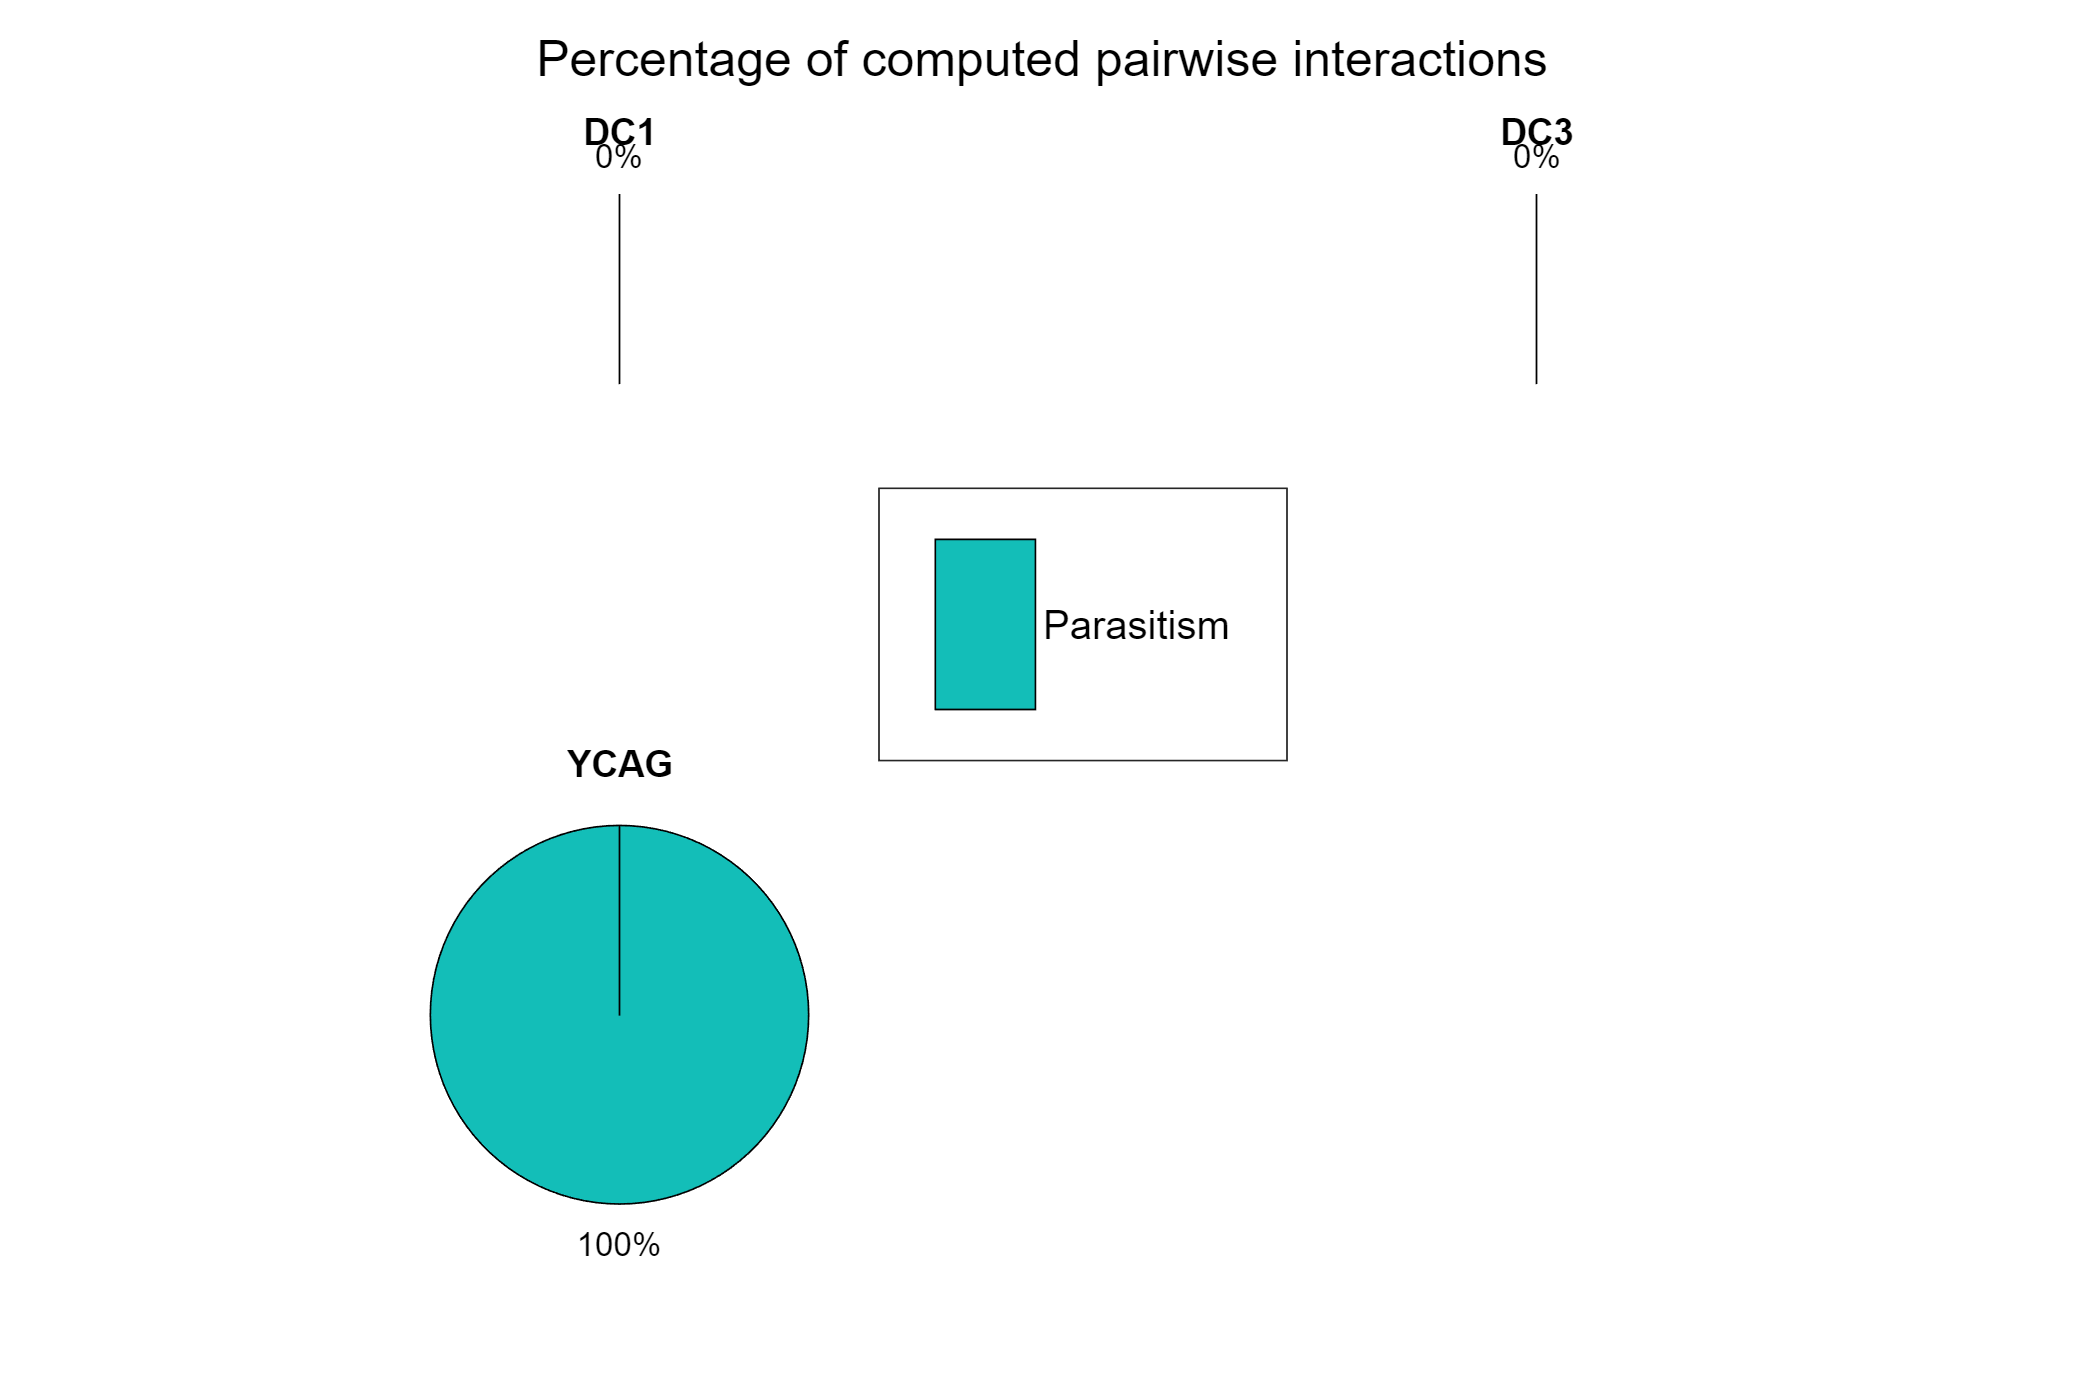

for i = 1:length(conditions)
    pairwiseInteractions=Interactions.(conditions{i});
    listIA=pairwiseInteractions(2:end,10);
    for j=1:length(typesIA)
        dat(j)=sum(strcmp(listIA(:),typesIA{j}));
    end
    subplot(2,2,i)
    pie(dat)
    set(gca,'FontSize',10)
    h=title(conditions{i});
    set(h,'interpreter','none')
    title(conditions{i})
end
legend1=legend(typesIA);
set(legend1,'Position',[0.42 0.45 0.2 0.2],'FontSize',12)
sgtitle('Percentage of computed pairwise interactions')

Next, the percentage of interactions will be calculated on different taxon levels (genus, family, order, class, phylum) using the taxon information contained in AGORA_infoFile.xlsx. Here, the interactions will be considered from the perspective of each joined microbe resulting in nine possible interactions total.

Calculate the percentage of interactions predicted for each taxon included in the list of microbes analyzed.

n points in the curve and vice versa?